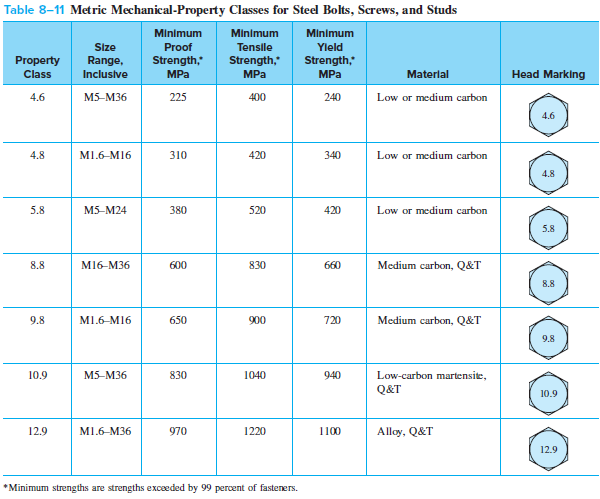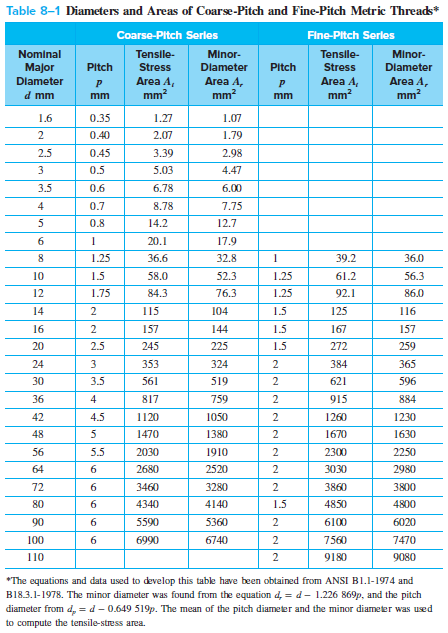

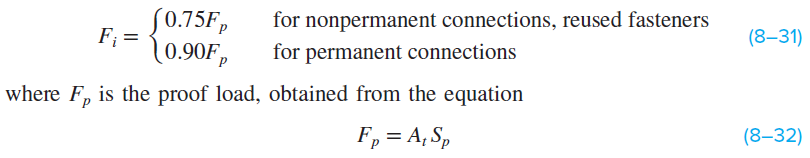

clear
format shortG
u = symunit;
S_y = 340 * u.MPa; %yield strength class 4.8
d = 4 * u.mm;
E = 207 * u.GPa;
A_t = 8.78 *u.mm^2; %tensile stress cross section area M4
A_r = 7.75 *u.mm^2; %areal fra roddiameter se table 8-1 i shigleys eller one note
A_d = pi/4 * d^2;   % Skaftareal [mm^2]
d_r = sqrt(4 * A_r / pi); % root diameteren
d_m = (d + d_r)/2; %middeldiameter
d_w = 7 * u.mm; % washer 
l = 0.7 * u.mm; %pitch
l_k =  29.9* u.mm; % = t + t = 2*t;    %Klemme længde (regnes kun til midt i underlagets nedre del) [mm]
L = 35* u.mm;% t + t + H;          % Boltlængde  [mm]
L_T = 35 * u.mm - 2.1* u.mm;          % Gevindlængde  [mm] %se også if statment nedenfor
l_d = L - L_T         % Skaft længde  [mm]

$$l\_d = \frac{21}{10}\,\mathrm{mm}$$

l_t = l_k - l_d         % Gevindlængde i indgreb  [mm]

$$l\_t = \frac{139}{5}\,\mathrm{mm}$$

f = 0.15; %friktionskoefficienten i gevind
fc = 0.10; %friktionskoefficienten i spændeskive
alpha = 30; %grader %30 grader er den typiske vinkel
d_c_min = 4.3 * u.mm; %mindste diameter på spændeskive
d_c_max = 8 * u.mm; %største diameter på spændeskive
d_c =  (d_c_min + d_c_max) / 2;%middel diameter på spændeskive

S_p = 0.85 * S_y; % proff strength
F_p = S_p * A_t; % proff force
F_i = 0.90 * F_p; % n_bolts% nonperm
F_i_ = vpa(unitConvert(F_i, u.N), 5)

$$F\_i\_ = 2283.7\,N$$

F_spring = [115.05 31.35 31.35] * u.N;
P = F_spring

$$P = \left(\begin{array}{ccc} \frac{2301}{20}\,N & \frac{627}{20}\,N & \frac{627}{20}\,N \end{array}\right)$$


tau_max = S_y;
T_max_calc = tau_max / 16 * (pi * d_r.^3); % torque at max torsion
T_max_calc_ = vpa(unitConvert(T_max_calc, u.N*u.m), 5)

$$T\_max\_calc\_ = 2.0693\,N\,m$$


lambda = atan(l/(pi*d_m)); %stigningsvinklen i gevind

T_for = (F_i * d_m/2) * ((tan(lambda) + f * secd(alpha)) /...
    (1 - f * tan(lambda) * secd(alpha))) + (F_i * fc * d_c)/2;
T_for_ = vpa(unitConvert(T_for, u.N*u.m), 5)

$$T\_for\_ = 1.6733\,N\,m$$


% I det tilfælde af at de to 𝑓 og 𝑓𝑐 = 0,15 ender det med at 𝐾 = 0.2
T_simpel = 0.2 * F_i * d; %den reducered formel når d_c = 1.25 * d

T_simpel_ = vpa(unitConvert(T_simpel, u.N * u.m), 4)

$$T\_simpel\_ = 1.827\,N\,m$$

Bolts and material stiffness

k_b = (A_d * A_t * E) / (A_d * l_t + A_t * l_d);
k_b = vpa(unitConvert((A_d * A_t * E) / (A_d * l_t + A_t * l_d), u.MN), 5) % ligning 8-17

$$k\_b = 62.099\,\frac{\mathrm{MN}}{m}$$



% Stivhed for matrialet
k_m = (pi * E * d * tand(alpha)) /...
    (2 * log(((l_k * tand(alpha) + d_w - d) * (d_w + d)) / ...
    ((l_k * tand(alpha) + d_w + d) * (d_w - d)) ) ); %ligning 8 -21

k_m = vpa(unitConvert(k_m, u.MN), 5)

$$k\_m = 776.92\,\frac{\mathrm{MN}}{m}$$


%Samling stivhedskontanten
C = k_b / (k_b + k_m)

$$C = 0.074013374437445909526106036491031$$


% Spændinger i bolten kan beregnes som
% sigma_b = F_b/A_t

P_b = vpa(unitConvert(C * P, u.N), 3)

$$P\_b = \left(\begin{array}{ccc} 8.52\,N & 2.32\,N & 2.32\,N \end{array}\right)$$

sigma_b = vpa(unitConvert((F_i_ + P_b) / A_t, u.MPa), 3)

$$sigma\_b = \left(\begin{array}{ccc} 261.0\,\mathrm{MPa} & 260.0\,\mathrm{MPa} & 260.0\,\mathrm{MPa} \end{array}\right)$$



% Sikkerhed imod flydning

n_p = vpa(unitConvert(S_p ./ sigma_b, 'SI'), 3) % ligning 8-28

$$n\_p = \left(\begin{array}{ccc} 1.11 & 1.11 & 1.11 \end{array}\right)$$

n_p = vpa(unitConvert(S_p * A_t ./ (C*P + F_i), 'SI'), 3)  % ligning 8-28

$$n\_p = \left(\begin{array}{ccc} 1.11 & 1.11 & 1.11 \end{array}\right)$$

**Springs**

1 kNm

clear
clf

L0 = 57.15e-3; % free length
L_extended = 111e-3;
L_retracted = 77e-3;
L_full = 124e-3

L_full =         0.124


k_axial = 0.57e3; % N/mm --> N/m % max kraft 41,87, max vandring 66,80, total lenth 123,95 L0 = 57,15
% E08500632250S % varenummer trækfjeder SODEMANN
x_axial = (L_full - L0) % 55e-3; % udspændt fjeder til træk af claw

x_axial =       0.06685




x_spring_pre = (L_retracted - L0)

x_spring_pre =       0.01985


%down to 77 from 110 (44)
F_axial_pre = k_axial * x_spring_pre

F_axial_pre =        11.314


F_axial = k_axial * x_axial

F_axial =        38.104


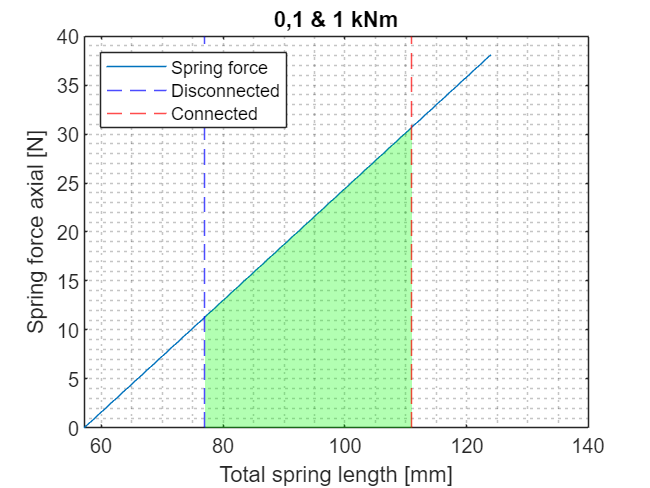


X = linspace(L0,L_full,100);
F_axial_plot = k_axial * (X-L0);
plot(X*1e3, F_axial_plot, DisplayName="Spring force")
hold on

fill_X = [linspace(L_retracted, L_extended, 100), L_extended, L_retracted]; % Extend to close area
fill_Y = [k_axial * (linspace(L_retracted, L_extended, 100) - L0), 0, 0]; % Add zeros for base
fill(fill_X * 1e3, fill_Y, 'g', 'FaceAlpha', 0.3, ...
    EdgeColor='none',HandleVisibility='off') % Fill with green color



xline(L_retracted*1e3, 'b--', DisplayName="Disconnected")
xline(L_extended*1e3, 'r--', DisplayName="Connected")
% xline(L0*1e3, 'g--', DisplayName="l_0")

xlabel("Total spring length [mm]")
ylabel("Spring force axial [N]")
legend('Location', 'northwest')
title("0,1 & 1 kNm")
grid('minor')
hold off

10 kNM

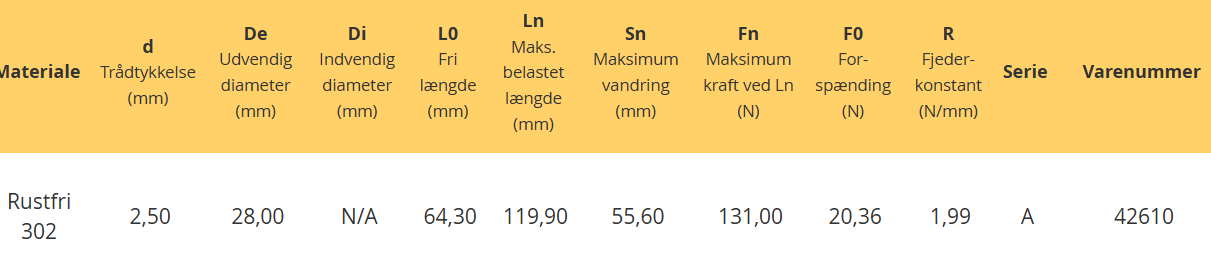

L0 = 64.30e-3

L0 =        0.0643


L_full = 119.9e-3

L_full =        0.1199


k_axial = 1.99e3; % N/mm --> N/m % max kraft 131,00, max vandring 55.60
% serie A  % varenummer 42610 trækfjeder SODEMANN rustfri

L_extended = 117e-3;
L_retracted = 72e-3;
x_axial = L_extended - L0

x_axial =        0.0527


x_spring_pre = (L_retracted - L0)

x_spring_pre =        0.0077


%down to 77 from 110 (44)
F_axial_pre = k_axial * x_spring_pre

F_axial_pre =        15.323


F_axial = k_axial * x_axial

F_axial =        104.87


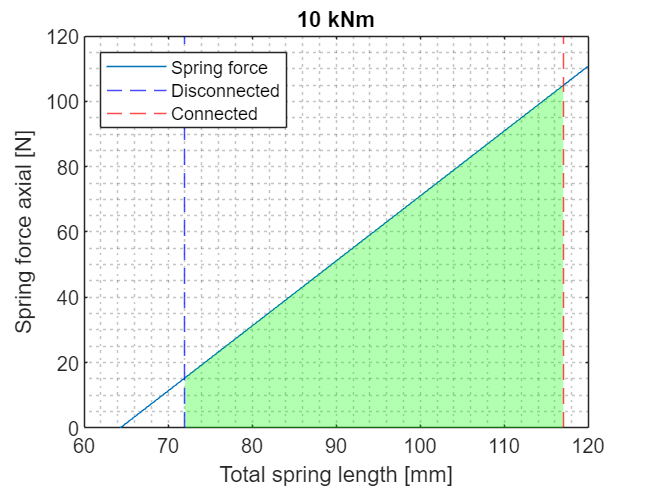


X = linspace(L0,L_full,100);
F_axial_plot = k_axial * (X-L0);
plot(X*1e3, F_axial_plot, DisplayName="Spring force")
hold on

fill_X = [linspace(L_retracted, L_extended, 100), L_extended, L_retracted]; % Extend to close area
fill_Y = [k_axial * (linspace(L_retracted, L_extended, 100) - L0), 0, 0]; % Add zeros for base
fill(fill_X * 1e3, fill_Y, 'g', 'FaceAlpha', 0.3, ...
    EdgeColor='none',HandleVisibility='off') % Fill with green color



xline(L_retracted*1e3, 'b--', DisplayName="Disconnected")
xline(L_extended*1e3, 'r--', DisplayName="Connected")
% xline(L0*1e3, 'g--', DisplayName="l_0")

xlabel("Total spring length [mm]")
ylabel("Spring force axial [N]")
legend('Location', 'northwest')
title("10 kNm")
grid('minor')
hold off

Weight to drag

g = 9.82; %
m = [4.7 1.9];
F_W = m * g;
f_s = 0.25;
F_fric = F_W * f_s

F_fric =        11.539       4.6645


**Bolt pretension**

Data

clear
format shortG
u = symunit;
S_y = 340 * u.MPa; %yield strength M4 bolt shigleys table 8-11
d = 4 * u.mm;
E = 207 * u.GPa;
A_t = 8.78 *u.mm^2; %tensile stress cross section area M4
A_r = 7.75 *u.mm^2; %areal fra roddiameter se table 8-1 i shigleys eller one note
A_d = pi/4 * d^2;   % Skaftareal [mm^2]d = [0.020 0.012 0.010 0.006]; % Bolt diameter metric class
p = 0.7*u.mm; %  %pitch (afstand fra top til top)
d_r = sqrt(4 * A_r / pi); % root diameteren
d_m = (d + d_r)/2;      % Mean diameter
d_p = (d + d_r)/2;      % Pitch diameter
D_Km = d * 1.3          % Mean bearing diameter at the nut or at the bolt head springer side 534

$$D\_Km = \frac{26}{5}\,\mathrm{mm}$$

d_w = 7*u.mm; % M20 M12 M10 M6 bolt type ISO 4762
d_h = 4.5*u.mm;% Hole diameter
l = p; % Amount of starting leads on thread
lambda = atan(l/(pi*d_m)); %stigningsvinklen i gevind
f = 0.18; %friktionskoefficienten i gevind
fc = 0.18; %friktionskoefficienten i spændeskive
alpha = 30; %grader %30 grader er den typiske vinkel
d_c_min = 4.3*u.mm;%0.011 %* u.mm; %mindste diameter på spændeskive
d_c_max = 8*u.mm; %d_c_min * 1.5%0.016 %* u.mm; %største diameter på spændeskive
% d_c_min * 1.5
d_c =  (d_c_min + d_c_max) / 2; %middel diameter på spændeskive
% n_bolts = [4 4 4 2]; % number of bolts


**Finding pretension according to shigleys**

S_p = 0.85 * S_y; % proff strength
F_p = S_p * A_t; % proff force
% F_i = 0.75 * F_p % n_bolts% nonperm
F_i = vpa(unitConvert(0.90 * F_p, u.N), 10) % n_bolts% nonperm

$$F\_i = 2283.678\,N$$

M = 0.2 * F_i * d

$$M = 1826.942399999999997817212715745\,N\,\mathrm{mm}$$

M_ = vpa(unitConvert(M, u.N * u.m))

$$M\_ = 1.826942399999999997817212715745\,N\,m$$

**Resilience of the bolt**

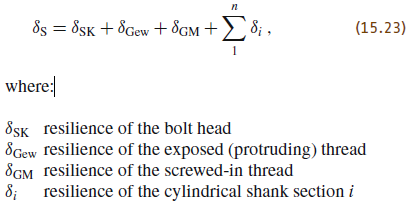

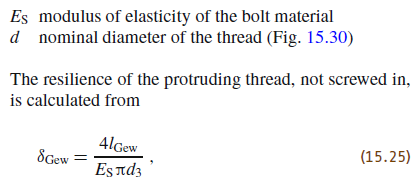

l_SK = d * 0.4; %for hexagon socket head cap screws (bolts),
E_s = 207 * u.GPa;   % young modulus for the bolt for stål 207 GPa E-modul
delta_SK = 4 * l_SK/(E_s * pi * d)

$$delta\_SK = \frac{8}{1035\,\pi }\,\frac{1}{\mathrm{GPa}}$$


l_Gew = 20 * u.mm; % length of the protruding thread (not engaged)
delta_Gew = 4 * l_Gew ./ (E_s * pi * d_r)

$$delta\_Gew = \frac{80\,\sqrt{31}}{6417\,\sqrt{\pi }}\,\frac{1}{\mathrm{GPa}}$$


E_M = E_s; % young modulus for the nut/hole
l_G = 0.5 * d_r % as a rule page 529. 10mm is half.

$$l\_G = \frac{\sqrt{31}}{2\,\sqrt{\pi }}\,\mathrm{mm}$$

delta_G = 4 * l_G / (E_s * pi * d_r)

$$delta\_G = \frac{2}{207\,\pi }\,\frac{1}{\mathrm{GPa}}$$


l_M = 0.33 * d % as a rule page 529.

$$l\_M = \frac{33}{25}\,\mathrm{mm}$$

delta_M = 4 * l_M / (E_M * pi * d)

$$delta\_M = \frac{11}{1725\,\pi }\,\frac{1}{\mathrm{GPa}}$$


delta_GM = delta_G + delta_M

$$delta\_GM = \frac{83}{5175\,\pi }\,\frac{1}{\mathrm{GPa}}$$


l_1 = 2.1 * u.mm; % full threaded
d_1 = d; % full threaded
delta_i = 4 * l_1 ./ (E_s * pi * d_1) % add one for each diameter size

$$delta\_i = \frac{7}{690\,\pi }\,\frac{1}{\mathrm{GPa}}$$


delta_S = vpa(delta_SK + delta_Gew + delta_GM + delta_i, 10) %exstendtion of the bolt

$$delta\_S = 0.0499567664\,\frac{1}{\mathrm{GPa}}$$

**Resilience of the material**

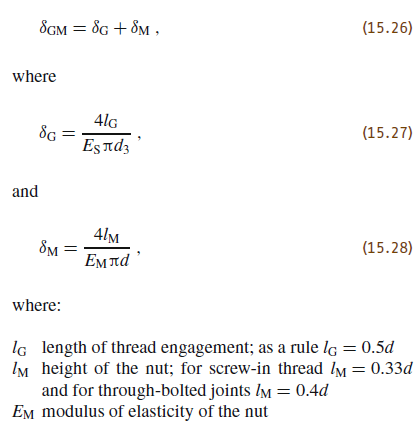

The resiliences of the individual shank areas

(15.32)

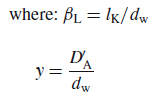

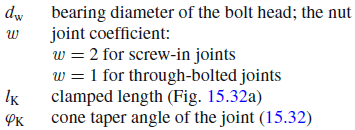

For screw in joint

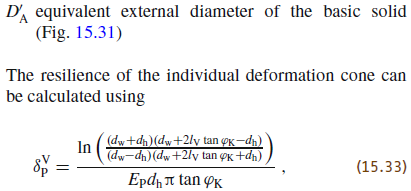

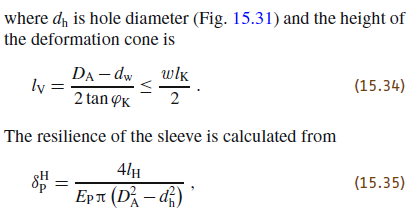

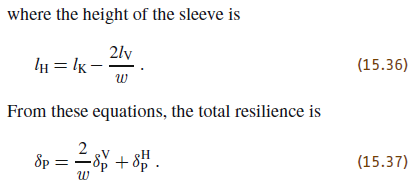

E_P = E_M

$$E\_P = 207\,\mathrm{GPa}$$

l_K = 30*u.mm;
D_A = 23*u.mm; % diameter ved tryk keglens max Fig. 15.31
D_A_mark = D_A; 


beta_L = l_K ./ d_w

$$beta\_L = \frac{30}{7}$$

y = D_A_mark ./ d_w

$$y = \frac{23}{7}$$

tan_phi_KE = 0.348 + 0.013 * log(beta_L) + 0.193 * log(y)

$$tan\_phi\_KE = \frac{193\,\log\left(\frac{23}{7}\right)}{1000}+\frac{13\,\log\left(\frac{30}{7}\right)}{1000}+\frac{87}{250}$$

l_V = (D_A - d_w) ./ (2*tan_phi_KE) % ligning 15.34

$$l\_V = \frac{16}{\frac{193\,\log\left(\frac{23}{7}\right)}{500}+\frac{13\,\log\left(\frac{30}{7}\right)}{500}+\frac{87}{125}}\,\mathrm{mm}$$


tan_phi_K = tan_phi_KE

$$tan\_phi\_K = \frac{193\,\log\left(\frac{23}{7}\right)}{1000}+\frac{13\,\log\left(\frac{30}{7}\right)}{1000}+\frac{87}{250}$$



delta_V_P = log( ( (d_w + d_h) .* (d_w + 2.*l_V .* tan_phi_K - d_h) ) ./...
     ( (d_w - d_h) .* (d_w + 2*l_V .* tan_phi_K + d_h) ) ) ./...
     (E_P .* d_h .* pi .* tan_phi_K) % ligning 15.33

$$delta\_V\_P = \begin{array}{l} \frac{2\,\log\left(\frac{23\,\left(\frac{5}{2}\,\mathrm{mm}+\sigma_{1}\right)}{5\,\left(\frac{23}{2}\,\mathrm{mm}+\sigma_{1}\right)}\right)}{1863\,\pi \,\left(\frac{193\,\log\left(\frac{23}{7}\right)}{1000}+\frac{13\,\log\left(\frac{30}{7}\right)}{1000}+\frac{87}{250}\right)}\,\frac{1}{\mathrm{GPa}\,\mathrm{mm}}\\ \mathrm{where}\\ \sigma_{1}=\frac{32\,\left(\frac{193\,\log\left(\frac{23}{7}\right)}{1000}+\frac{13\,\log\left(\frac{30}{7}\right)}{1000}+\frac{87}{250}\right)}{\frac{193\,\log\left(\frac{23}{7}\right)}{500}+\frac{13\,\log\left(\frac{30}{7}\right)}{500}+\frac{87}{125}}\,\mathrm{mm} \end{array}$$


w = 2; % joint coeffecient; 2 for screw-in joints, 1 for through-bolted joints

l_H = l_K - 2*l_V/w; %15.5 + (23+1.5)/2; %l_k - 2*l_V/w % 15.36

delta_H_P = vpa((4 * l_H) ./ (E_P * pi .* (D_A.^2 - d_h.^2)),10)

$$delta\_H\_P = 0.0002005606279\,\frac{1}{\mathrm{GPa}\,\mathrm{mm}}$$



delta_P = vpa(2/w * delta_V_P + delta_H_P, 10)

$$delta\_P = 0.0008476900115\,\frac{1}{\mathrm{GPa}\,\mathrm{mm}}$$


f_Z = (3 + 3)*u.mcm % surface roughness 10-40

$$f\_Z = 6\,\mathrm{\mu m}$$

F_Z = vpa(f_Z ./ (delta_S + delta_P),10)

$$F\_Z = \frac{6.0}{0.0499567664\,\frac{1}{\mathrm{GPa}}+0.0008476900115\,\frac{1}{\mathrm{GPa}\,\mathrm{mm}}}\,\mathrm{\mu m}$$

**Tightning torque needed found with springer**

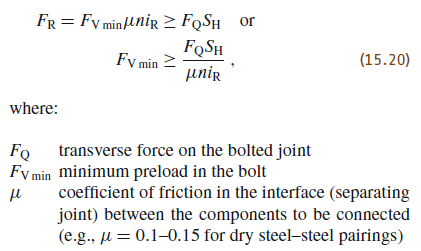

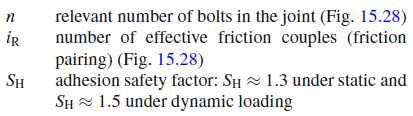

$F_A$ - additionally loaded by an axial working load 

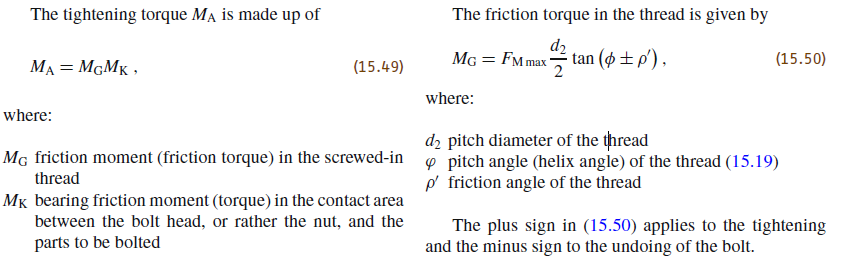

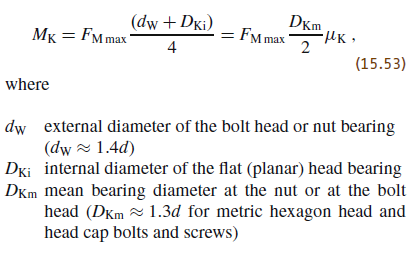

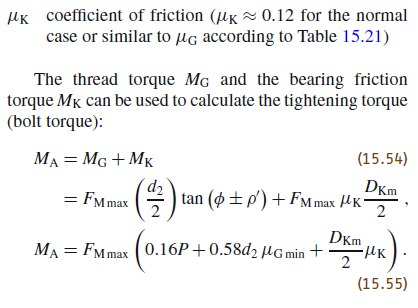

Med springer

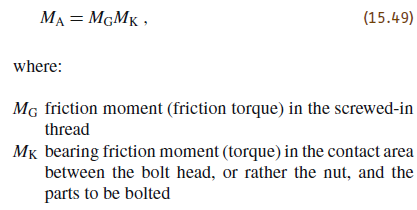

% F_Z = 0; % The resulting loss of force is called the loss of preload
F_Mmin = F_i + F_Z

$$F\_Mmin = 2283.6779999999999972715158946812\,N+\frac{6.0}{0.049956766402350821602851294045422\,\frac{1}{\mathrm{GPa}}+0.0008476900115139916001946902845976\,\frac{1}{\mathrm{GPa}\,\mathrm{mm}}}\,\mathrm{\mu m}$$

alpha_A = 1.6% tightening factor % Table 15.19: Tightening with torque wrench

alpha_A =           1.6


F_Mmax = alpha_A * F_Mmin % 

$$F\_Mmax = 3653.8847999999999956344254314899\,N+\frac{9.6}{0.049956766402350821602851294045422\,\frac{1}{\mathrm{GPa}}+0.0008476900115139916001946902845976\,\frac{1}{\mathrm{GPa}\,\mathrm{mm}}}\,\mathrm{\mu m}$$

mu_G_min = 0.12; % Table 15.21 dry black tempered / steel blank
mu_K = 0.12; % for the normal case or similar to mu_G according to Table 15.21
M_A = F_Mmax .* (0.16*p + 0.58*d_p * mu_G_min + D_Km/2 * mu_K)

$$M\_A = \left(3653.8847999999999956344254314899\,N+\frac{9.6}{0.049956766402350821602851294045422\,\frac{1}{\mathrm{GPa}}+0.0008476900115139916001946902845976\,\frac{1}{\mathrm{GPa}\,\mathrm{mm}}}\,\mathrm{\mu m}\right)\,\left(\frac{352}{625}\,\mathrm{mm}+\frac{87\,\sqrt{31}}{2500\,\sqrt{\pi }}\,\mathrm{mm}\right)$$


unitConvert(1 *u.J/u.m^3, "SI")

$$ans = \frac{\mathrm{kg}}{m\,s^{2}}$$

unitConvert(delta_P, "SI")

$$ans = 0.0000000008476900115139916001946902845976\,\frac{s^{2}}{\mathrm{kg}}$$